# 插值

1、通过离散傅里叶变换的平移/调制性质得到

2、通过离散傅里叶变换的频谱补零得到

3、通过与插值核的卷积得到√

sinc插值

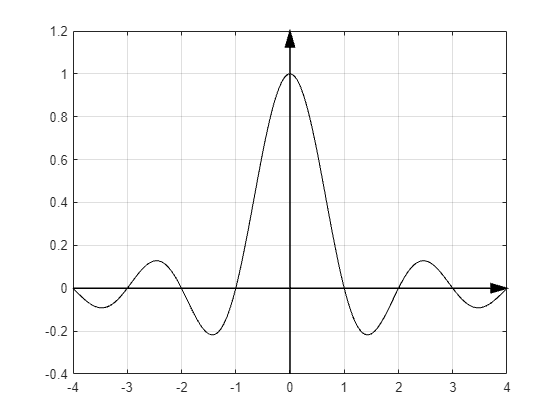

% 插值核
N = 40;
t = -4:1/N:4-1/N;
                                                            
st = sinc(t);
%{
st = sin(pi*t)./(pi*t);
%}

figure
plot(t,st,'k')
axis([-4 4,-0.4 1.2])
grid on

% 坐标轴
arrow([-4,0],[4,0],'Color','k','Linewidth',1);
arrow([0,-0.4],[0,1.2],'Color','k','Linewidth',1);

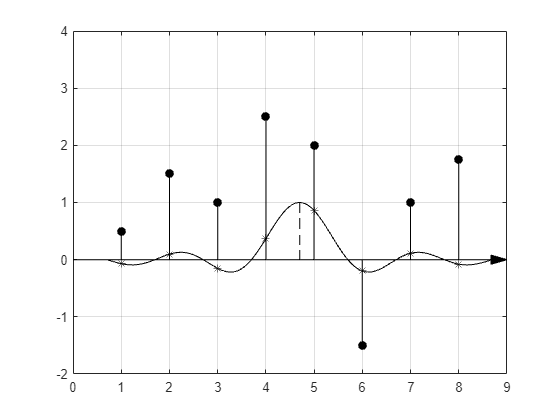


% 初始样本
x2 = 1:8;

gx = [1,3,2,5,4,-3,2,3.5]/2;

figure
plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
axis([0 9,-2 4])
grid on

for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k');
end

% 坐标轴
arrow([0,0],[9,0]);

a = 4.7;

plot(t+a,st,'k'),hold on,plot(x2,sinc(x2-a),'k*')

line([a,a],[sinc(0),0],'Color','k','LineStyle','--')

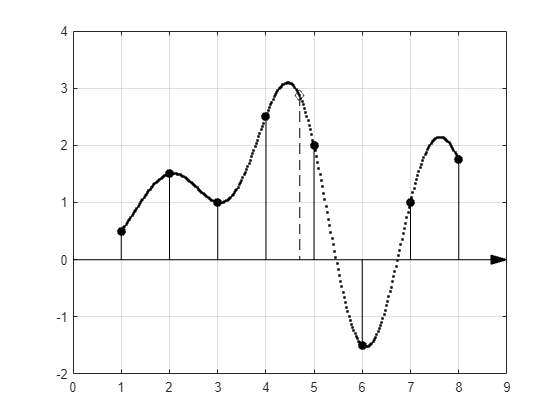


% H = [];
% %% 插值运算
% a = 1:1/2:8-1/2
% for a = 1:1/2:8-1/2
%     t1 = a-4:1:a+3;
%     sinc(t1)
% end

A = figure();
plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
axis([0 9,-2 4])
grid on

for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k')
end

% 坐标轴
arrow([0,0],[9,0]);

for b = 1:1/N:8-1/N
    t2 = b-1:-1:b-8;
    gx_f = sinc(t2)*gx';
    figure(A)
    plot(b,gx_f,'k.'),hold on
    
    if b == a
       plot(b,gx_f,'kd'),hold on
       line([b,b],[gx_f,0],'Color','k','LineStyle','--')
    end
end


%% 绘图
set(figure,'position',[100,100,1200,1200]);

subplot(311),plot(t,st,'k')
title('(a)插值核'),xlabel('x1'),ylabel('hx')
axis([-4 4,-0.4 1.2])
grid on
arrow([-4,0],[4,0],'Color','k','Linewidth',1);
arrow([0,-0.4],[0,1.2],'Color','k','Linewidth',1);

subplot(312),plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
plot(t+a,st,'k'),hold on
plot(x2,sinc(x2-a),'k*'),hold on 
title('(b)插值运算'),xlabel('x2'),ylabel('gx')
axis([0 9,-2 4])
grid on
for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k');
end
for i = 1:8
    line([x2(i),x2(i)],[sinc(i-a),0],'Color','k');
end
line([a,a],[sinc(0),0],'Color','k','LineStyle','--')
arrow([0,0],[9,0]);

subplot(313),plot(x2,gx,'ko','MarkerFaceColor','k'),hold on
title('(c)插值后的信号'),xlabel('x2'),ylabel('gx_f')
axis([0 9,-2 4])
grid on
for i = 1:8
    line([x2(i),x2(i)],[gx(i),0],'Color','k')
end
for b = 1:1/N:8-1/N
    t2 = b-1:-1:b-8;
    gx_f = sinc(t2)*gx';
    plot(b,gx_f,'k.'),hold on
    if b == 4.7
       plot(b,gx_f,'kd'),hold on
       line([b,b],[gx_f,0],'Color','k','LineStyle','--')
    end
end
arrow([0,0],[9,0]);

sgtitle('图2.14 使用sinc函数插值的图')

插值核的归一化

对于截断后的核，需要进行归一化处理，使其增益单位化，否则采样点上的权值和不再等于1，并且在不同插值点x之间存在差异。

插值核的加权

当使用截断后的插值核对存在陡峭边缘的函数进行插值时，会出现一种称为Gibbs效应的振铃现象。为减小这种影响，应对插值核进行锐化窗加权。

N = 500;
t = -8:1/N:8-1/N;

ans = 8000

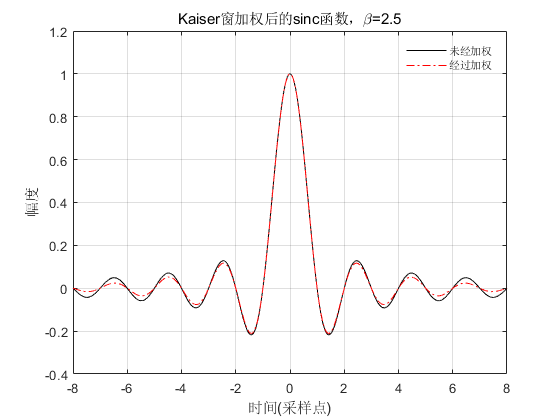


st = sinc(t);
%{
st = sin(pi*t)./(pi*t);
%}

figure
p1 = plot(t,st,'k');hold on
p2 = plot(t,st.*kaiser(length(t),2.5)','r-.');  % kaiser窗加权
title('Kaiser窗加权后的sinc函数，\beta=2.5'),xlabel('时间(采样点)'),ylabel('幅度')
axis([-8 8,-0.4 1.2])
grid on

legend('boxoff');
lgd = legend([p1,p2],{'未经加权','经过加权'},'FontSize',8,'TextColor','k','Location','northeast','NumColumns',1);

% title(lgd,'My Legend Title')

为提高计算效率，可以将升采样后的插值核存储在表格中，这样就无需对每个插值点计算sinc函数、窗和归一化因子，

而只需使用最接近移动位置处的表格系数。

x_tmp = repmat(-4:3,[16,1])

x_tmp =     -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3
    -4    -3    -2    -1     0     1     2     3


repmat(((1:16)/16).',[1,8])

ans =     0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625    0.0625
    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250    0.1250
    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875    0.1875
    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500    0.2500
    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125    0.3125
    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750    0.3750
    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375    0.4375
    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000    0.5000
    0.5625    0.5625    0.5625    0.5625    0.5625    0.5625    0.5625    0.5625
    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250    0.6250


x_tmp = x_tmp + repmat(((1:16)/16).',[1,8])

x_tmp =    -3.9375   -2.9375   -1.9375   -0.9375    0.0625    1.0625    2.0625    3.0625
   -3.8750   -2.8750   -1.8750   -0.8750    0.1250    1.1250    2.1250    3.1250
   -3.8125   -2.8125   -1.8125   -0.8125    0.1875    1.1875    2.1875    3.1875
   -3.7500   -2.7500   -1.7500   -0.7500    0.2500    1.2500    2.2500    3.2500
   -3.6875   -2.6875   -1.6875   -0.6875    0.3125    1.3125    2.3125    3.3125
   -3.6250   -2.6250   -1.6250   -0.6250    0.3750    1.3750    2.3750    3.3750
   -3.5625   -2.5625   -1.5625   -0.5625    0.4375    1.4375    2.4375    3.4375
   -3.5000   -2.5000   -1.5000   -0.5000    0.5000    1.5000    2.5000    3.5000
   -3.4375   -2.4375   -1.4375   -0.4375    0.5625    1.5625    2.5625    3.5625
   -3.3750   -2.3750   -1.3750   -0.3750    0.6250    1.6250    2.6250    3.6250


hx = sinc(x_tmp)

hx =    -0.0158    0.0211   -0.0321    0.0662    0.9936   -0.0584    0.0301   -0.0203
   -0.0314    0.0424   -0.0650    0.1392    0.9745   -0.1083    0.0573   -0.0390
   -0.0464    0.0629   -0.0976    0.2177    0.9432   -0.1489    0.0808   -0.0555
   -0.0600    0.0818   -0.1286    0.3001    0.9003   -0.1801    0.1000   -0.0693
   -0.0718    0.0985   -0.1568    0.3850    0.8469   -0.2016    0.1144   -0.0799
   -0.0811    0.1120   -0.1810    0.4705    0.7842   -0.2139    0.1238   -0.0871
   -0.0876    0.1218   -0.1998    0.5550    0.7136   -0.2172    0.1281   -0.0908
   -0.0909    0.1273   -0.2122    0.6366    0.6366   -0.2122    0.1273   -0.0909
   -0.0908    0.1281   -0.2172    0.7136    0.5550   -0.1998    0.1218   -0.0876
   -0.0871    0.1238   -0.2139    0.7842    0.4705   -0.1810    0.1120   -0.0811


x_tmp16 =    -63   -47   -31   -15     1    17    33    49
   -62   -46   -30   -14     2    18    34    50
   -61   -45   -29   -13     3    19    35    51
   -60   -44   -28   -12     4    20    36    52
   -59   -43   -27   -11     5    21    37    53
   -58   -42   -26   -10     6    22    38    54
   -57   -41   -25    -9     7    23    39    55
   -56   -40   -24    -8     8    24    40    56
   -55   -39   -23    -7     9    25    41    57
   -54   -38   -22    -6    10    26    42    58


x_tmp16 =      1    17    33    49    65    81    97   113
     2    18    34    50    66    82    98   114
     3    19    35    51    67    83    99   115
     4    20    36    52    68    84   100   116
     5    21    37    53    69    85   101   117
     6    22    38    54    70    86   102   118
     7    23    39    55    71    87   103   119
     8    24    40    56    72    88   104   120
     9    25    41    57    73    89   105   121
    10    26    42    58    74    90   106   122


kwin = repmat(kaiser(8,2.5).',[16,1])

kwin =     0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040


ans =     0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040
    0.3040    0.5851    0.8343    0.9806    0.9806    0.8343    0.5851    0.3040


x = kwin.*hx;
hx = hx./repmat(sum(hx,2),[1,8])    %核的归一化

hx =    -0.0160    0.0215   -0.0326    0.0673    1.0092   -0.0594    0.0306   -0.0206
   -0.0324    0.0437   -0.0670    0.1436    1.0049   -0.1117    0.0591   -0.0402
   -0.0485    0.0658   -0.1020    0.2276    0.9864   -0.1557    0.0845   -0.0580
   -0.0636    0.0867   -0.1362    0.3178    0.9534   -0.1907    0.1059   -0.0733
   -0.0768    0.1054   -0.1678    0.4119    0.9061   -0.2157    0.1225   -0.0855
   -0.0875    0.1208   -0.1951    0.5073    0.8455   -0.2306    0.1335   -0.0939
   -0.0949    0.1320   -0.2165    0.6013    0.7731   -0.2353    0.1388   -0.0984
   -0.0987    0.1382   -0.2303    0.6908    0.6908   -0.2303    0.1382   -0.0987
   -0.0984    0.1388   -0.2353    0.7731    0.6013   -0.2165    0.1320   -0.0949
   -0.0939    0.1335   -0.2306    0.8455    0.5073   -0.1951    0.1208   -0.0875
